x=[0 1 2];
y=[1 3 0];
[pol] = Lagrange(x,y)
polinomio_str = coeficientes_a_polinomio_newton(pol)

x=0:0.1:2
y=x.^2*pol(1,1)+x*pol(1,2)+pol(1,3)
plot(x,y)
y_aux=1.^2*pol(1,1)+1*pol(1,2)+pol(1,3)


x=[0 1 2];
y=[1 3 0];

[Tabla] = Spline(x,y,1)

Tabla =      2     1
    -3     6


polinomiosStr = polinomiosSplineLineal2(Tabla, x)

polinomiosStr = 2×3 cell array
    {'Polinomio para x entre [0.000000, 1.000000]: (2.000000)*(x) + 1.000000↵↵' }    {[2.0*x + 1.0]}    {[0 1]}
    {'Polinomio para x entre [1.000000, 2.000000]: (-3.000000)*(x) + 6.000000↵↵'}    {[6.0 - 3.0*x]}    {[1 2]}


aux=polinomiosStr(:,2)'

aux = 1×2 cell array
    {[2.0*x + 1.0]}    {[6.0 - 3.0*x]}


jj=cell2mat(polinomiosStr(:,3))

jj =      0     1
     1     2


condiciones=[];
syms x
for i=1:size(jj,1)
aux_1=jj(i,1) < x;
aux_2=x < jj(i,2);
aux_3=aux_1 & aux_2;
condiciones=[condiciones,aux_3];
end
jh=cell2sym(aux)

$$jh = \left(\begin{array}{cc} 2.0\,x+1.0 & 6.0-3.0\,x \end{array}\right)$$

funciones=matlabFunction(jh)

funciones = function_handle with value:
    @(x)[x.*2.0+1.0,x.*-3.0+6.0]


condiciones=matlabFunction(condiciones)

condiciones = function_handle with value:
    @(x)[(0.0<x)&(x<1.0),(1.0<x)&(x<2.0)]


sol=@(x)sum(funciones(x).*condiciones(x))

sol = function_handle with value:
    @(x)sum(funciones(x).*condiciones(x))


sol_f=sol(x)

$$sol\_f = \left(0<x\wedge x<1\right)\,\left(2\,x+1\right)+\left(1<x\wedge x<2\right)\,\left(6-3\,x\right)$$

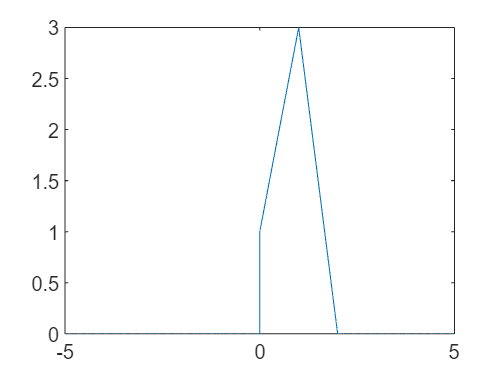

fplot(sol_f)

function polinomiosStr = polinomiosSplineLineal(coeficientes, puntosX)
    % coeficientes: una matriz donde cada fila contiene los coeficientes
    %              de un polinomio de spline lineal
    % puntosX: un vector con los puntos x_i que definen los intervalos
    
    numPolinomios = size(coeficientes, 1);
    
    polinomiosStr = cell(numPolinomios, 3); % Añadir dos columnas adicionales
    
    for i = 1:numPolinomios
        % Obtener los coeficientes del polinomio actual
        a = coeficientes(i, 1);
        b = coeficientes(i, 2);
        
        % Obtener los puntos de inicio y fin del intervalo actual
        xi = puntosX(i);
        xi1 = puntosX(i + 1);
        
        % Crear el polinomio en formato de cadena
        polinomioStr = sprintf('(%f)*(x) + %f', a, b);
        
        % Guardar el polinomio en la matriz de strings
        polinomiosStr{i, 1} = sprintf('Polinomio para x entre [%f, %f]: %s\n\n', xi, xi1, polinomioStr);
        
        % Guardar la función en la segunda columna
        polinomiosStr{i, 2} = str2sym(sprintf('%f*x + %f', a, b));
        
        % Guardar el intervalo en la tercera columna
        polinomiosStr{i, 3} = [xi, xi1];
    end
end
